# **Vehicle Performance Analysis (CoDPAD m1-1)**

CoDPAD module 1 : Vehicle performance analysis

This part suggests results achieved from fligth test based on refSigTest. Results from raw response data to estimated transfer function will be provided. Please refer to CoDPAD document Ch. 1.1. for further details.

[https://nearth.atlassian.net/l/c/jtPt190P](https://nearth.atlassian.net/l/c/jtPt190P)

[https://nearth.atlassian.net/l/c/3fbf1ss9](https://nearth.atlassian.net/l/c/3fbf1ss9)

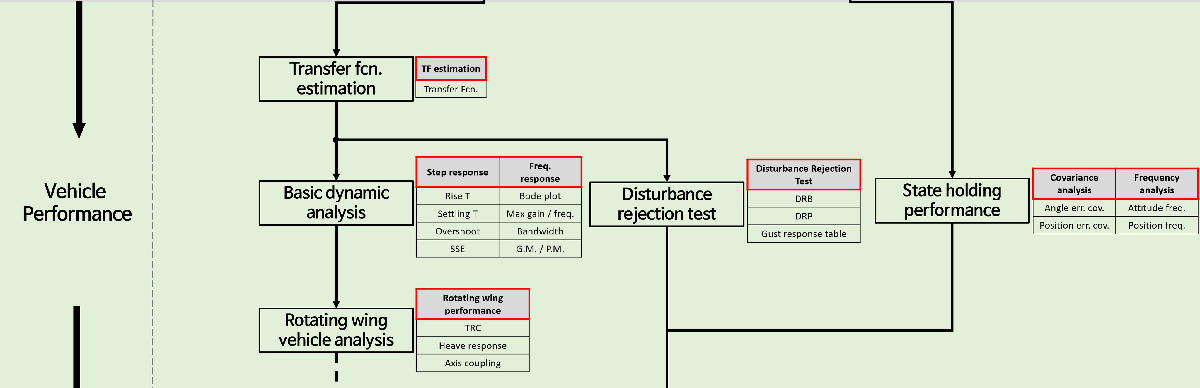

**Sweep Signal Equation**

#### 
$$\theta(t) = \omega_{min}t + c_2(\omega_{max}-\omega_{min})({T\over c_{min}}*e^{{c_1\over T}*t}-t) - res$$


global nN nD

## Basic parameters

#### **index guide**

1 : roll step test

2 : v step test

3 : Y step test

4 : pitch step test

5 : u step test

6 : X step test

7 : yaw step test

8 : w step test

9 : Z step test

#### **User Input**

specify this script's mode of operation (to plot or to estimate tf), missionIdx of interest, and the address of gdLogFile.

doplot = 1

doplot = 1

missionIdxToPlot = 10

missionIdxToPlot = 10

gdLogFile = "/Users/imjaehan/Desktop/MATLAB-devel/matlab_system_analysis/gdLog_210702_110357.csv"

gdLogFile = "/Users/imjaehan/Desktop/MATLAB-devel/matlab_system_analysis/gdLog_210702_110357.csv"

% Transfer function params
nN = 1;
nD = 2;

% DO NOT CHANGE _ params.
c1 = 4; c2 = 0.01866;
wmin = 0.4*2*pi;
wmax = 10*2*pi;
T = 20;
d2r = pi/180;
r2d = 1/d2r;

## Load data

Proved address to gdLogFile of interest.

% [data, data_time] = loader(gdLogFile);
% data_time = seconds(data_time);

data = readtable(gdLogFile);
data_time = data.rosTime;
data_time = seconds(data_time);
data_time = data_time - data_time(1);

%% Coodinate adjustment
posNed = [data.posNED_m_0,data.posNED_m_1,data.posNED_m_2];
posNedCmd = [data.posCmdNED_m_0,data.posCmdNED_m_1,data.posCmdNED_m_2];
velNed = [data.velNED_mps_0,data.velNED_mps_1,data.velNED_mps_2];
velNedCmd = [data.velCmdHdg_mps_0,data.velCmdHdg_mps_1,data.velCmdHdg_mps_2];
dcmI2body = angle2dcm(wrapToPi(data.rpy_deg_2*d2r), zeros(size(data,1),1), zeros(size(data,1),1),'zyx');

posXyz = zeros(size(posNed));
posXyzCmd = zeros(size(posNed));
velUvw = zeros(size(posNed));
velUvwCmd = velNedCmd;
posXyzCmd = posNedCmd;
posXyz = posNed;
for i = 1:size(posNed,1)
    posXyz(i,:) = dcmI2body(:,:,i) * posNed(i,:)';
    posXyzCmd(i,:) = dcmI2body(:,:,i) * posNedCmd(i,:)';
    velUvw(i,:) = dcmI2body(:,:,i) * velNed(i,:)';
%     velUvwCmd(i,:) = dcmI2body(:,:,i) * velNedCmd(i,:)';
end

posXyz_0 = posXyz(:,1);
posXyz_1 = posXyz(:,2);
posXyz_2 = posXyz(:,3);
posXyzCmd_0 = posXyzCmd(:,1);
posXyzCmd_1 = posXyzCmd(:,2);
posXyzCmd_2 = posXyzCmd(:,3);
velUvw_0 = velUvw(:,1);
velUvw_1 = velUvw(:,2);
velUvw_2 = velUvw(:,3);
velUvwCmd_0 = velUvwCmd(:,1);
velUvwCmd_1 = velUvwCmd(:,2);
velUvwCmd_2 = velUvwCmd(:,3);


## Data parsing

refSigTest consists of total 7 missions. (3 step tests, 3 sweep test, 1 hold test) Step test and sweep test consist of 3 subjobs each. Holding test consists of 2 subjobs.  This part parses whole gdLogdata into individual test sets (each subjobs). Refer to CoDPAD document Ch. 1-1 for more details.

[https://nearth.atlassian.net/l/c/hQRhdouM](https://nearth.atlassian.net/l/c/hQRhdouM)

testStartFlag = [];
testFinishFlag = [];
missionStartFlag = [];
missionFinishFlag = [];
fcMode = data.fcMcMode;
missionType = data.missionType;

ns = 1; nf = 1; nsm = 1; nfm = 1;
for i = 2:length(fcMode)
    if fcMode(i) ~= fcMode(i-1) && fcMode(i) == 2
        testStartFlag(ns) = i; ns = ns+1;
    elseif fcMode(i) ~= fcMode(i-1) && fcMode(i-1) == 2
        testFinishFlag(nf) = i; nf = nf+1;
    end
    if fcMode(i-1) == 0 && fcMode(i) == 1
        missionStartFlag(nsm) = i; nsm = nsm + 1;
    elseif fcMode(i-1) == 1 && fcMode(i) == 0
        missionFinishFlag(nfm) = i; nfm = nfm + 1;
    end
end

responseSet = [data.rpy_deg_0*d2r,velUvw_1,posXyz_1,data.rpy_deg_1*d2r,velUvw_0,posXyz_0,data.rpy_deg_2*d2r,velUvw_2,posXyz_2];
cmdSet = [data.rpdCmd_deg_deg_mps_0*d2r,velUvwCmd_1,posXyzCmd_1,data.rpdCmd_deg_deg_mps_1*d2r,velUvwCmd_0,posXyzCmd_0,data.yawSp_deg*d2r,velUvwCmd_2,posXyzCmd_2];

gimbaldev = sqrt((data.gimbalRpy_deg_0*d2r).^2 + (data.gimbalRpy_deg_1*d2r).^2 + (data.gimbalRpy_deg_2*d2r).^2);

n = missionIdxToPlot; % Select test index

m = n;
if m > 9
    m = m-9;
end
Cmd = cmdSet(testStartFlag(n):testFinishFlag(n)-1,m);
time = data_time(testStartFlag(n):testFinishFlag(n)-1);
response = responseSet(testStartFlag(n):testFinishFlag(n)-1,m);



## **Transfer Function Estimation**

This part estimates transfer function for each test sets. The results are saved in struct "tfResult".

if doplot == 0
    %% TF estimation - use as required
    
    % Basic TF - All (Step & Sweep) - NOT USED AT THE MOMENT
%     tfResult = {};
%     for i = 1:18
%         [Num,Den,delay]=estimate_tf(i,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
%         tfResult{i}.Num = Num;
%         tfResult{i}.Den = Den;
%         tfResult{i}.Delay = delay;
%         A = [num2str(i),'th transfer function estimation complete'];
%         disp(A)
%         tfResult{i}
%     end
    
    % Basic TF - (Step test only)
    tfResult = {};
    for i = 1:9
        [Num,Den,delay]=estimate_tf(i,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
        tfResult{i}.Num = Num;
        tfResult{i}.Den = Den;
        tfResult{i}.Delay = delay;
        A = [num2str(i),'th transfer function estimation complete'];
        disp(A)
        tfResult{i}
    end
    
    % Mix TF - EXPERIMENTAL - NOT USED AT THE MOMENT
    % tfResult_mix = {};
    % for i = 1:3
    %     [Num,Den,delay]=estimate_tf(3,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
    %     tfResult_mix{i}.Num = Num;
    %     tfResult_mix{i}.Den = Den;
    %     tfResult_mix{i}.Delay = delay;
    %     A = [num2str(i),'th transfer function estimation complete'];
    %     disp(A)
    % end
    
    %% Sweep signal
    % res = c2*(wmax-wmin)*T/c1;
    % omega = wmin + (exp((time-time(1))/T*c1)-1)*c2*(wmax-wmin);
    % freq = omega/2/pi;
    % theta = wmin*t + c2*(wmax-wmin)*(T/c1*exp(c1/T*t)-t) - res;
end


## Plotting

if doplot == 1
range = testStartFlag(n):testFinishFlag(n)-1;


### **Vehicle Attitude Response (rpy)**

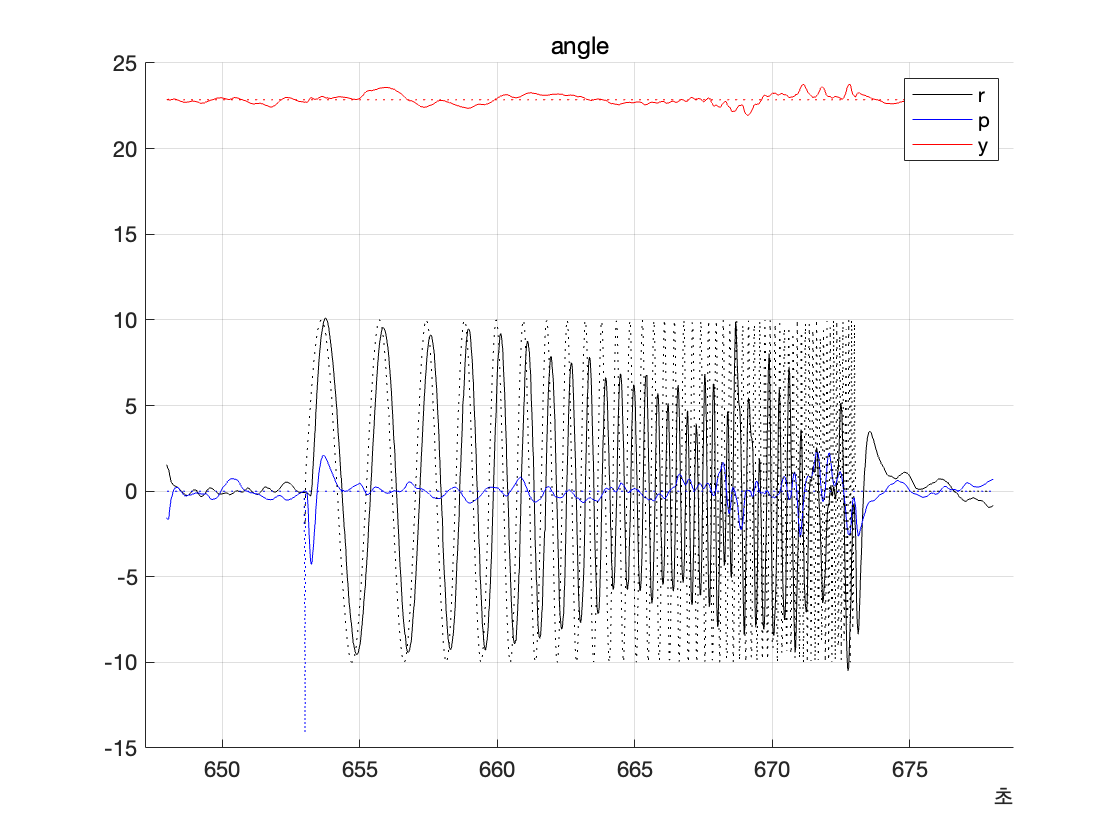

figure(10)
clf
hold on
grid on
plot(time,data.rpy_deg_0(range),'k')
plot(time,data.rpy_deg_1(range),'b')
plot(time,data.rpy_deg_2(range),'r')
plot(time,data.rpdCmd_deg_deg_mps_0(range),'k:')
plot(time,data.rpdCmd_deg_deg_mps_1(range),'b:')
plot(time,data.yawSp_deg(range),'r:')
title('angle')
legend('r','p','y')

### **Vehicle Velocity Response (uvw)**

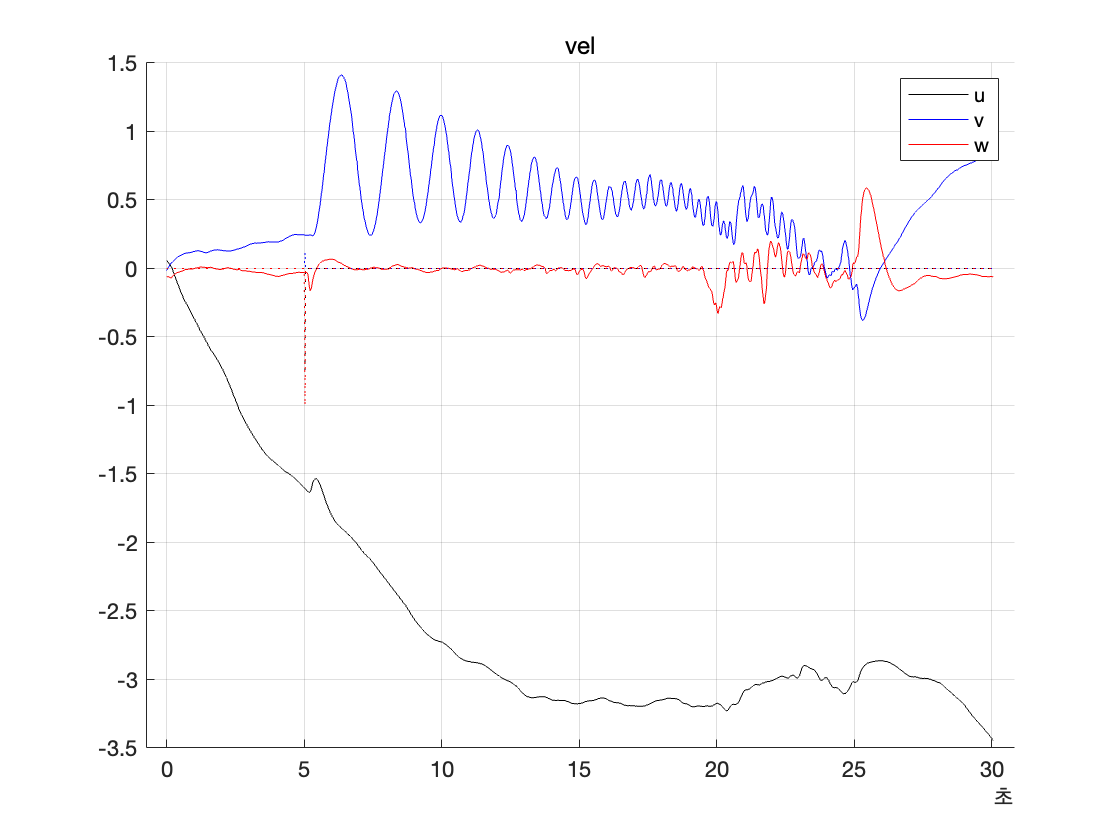

figure(11)
% clf
hold on
grid on
plot(time-time(1),velUvw_0(range),'k')
plot(time-time(1),velUvw_1(range),'b')
plot(time-time(1),-velUvw_2(range),'r')
plot(time-time(1),velUvwCmd_0(range),'k:')
plot(time-time(1),velUvwCmd_1(range),'b:')
plot(time-time(1),-velUvwCmd_2(range),'r:')
title('vel')
legend('u','v','w')

### **Vehicle Position Response (XYZ)**

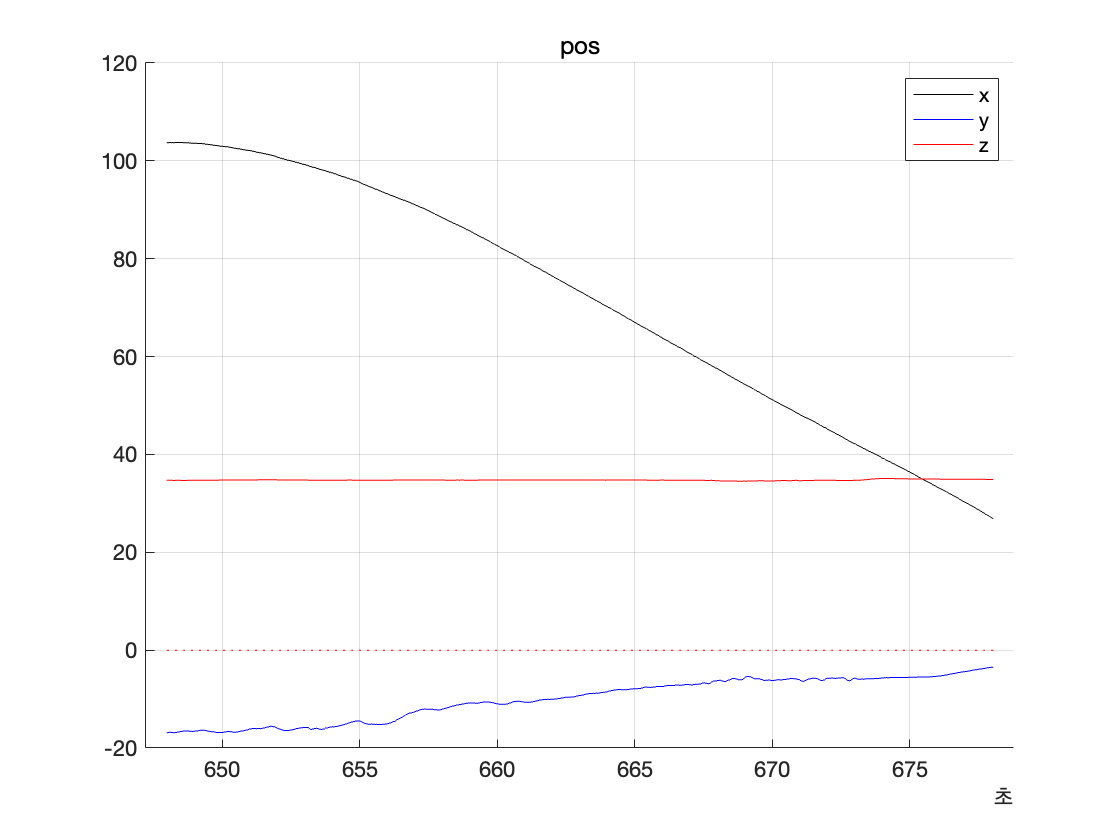

figure(12)
clf
hold on
grid on
plot(time,posXyz_0(range),'k')
plot(time,posXyz_1(range),'b')
plot(time,-posXyz_2(range),'r')
plot(time,posXyzCmd_0(range),'k:')
plot(time,posXyzCmd_1(range),'b:')
plot(time,-posXyzCmd_2(range),'r:')
title('pos')
legend('x','y','z')

### **Gimbal Response**

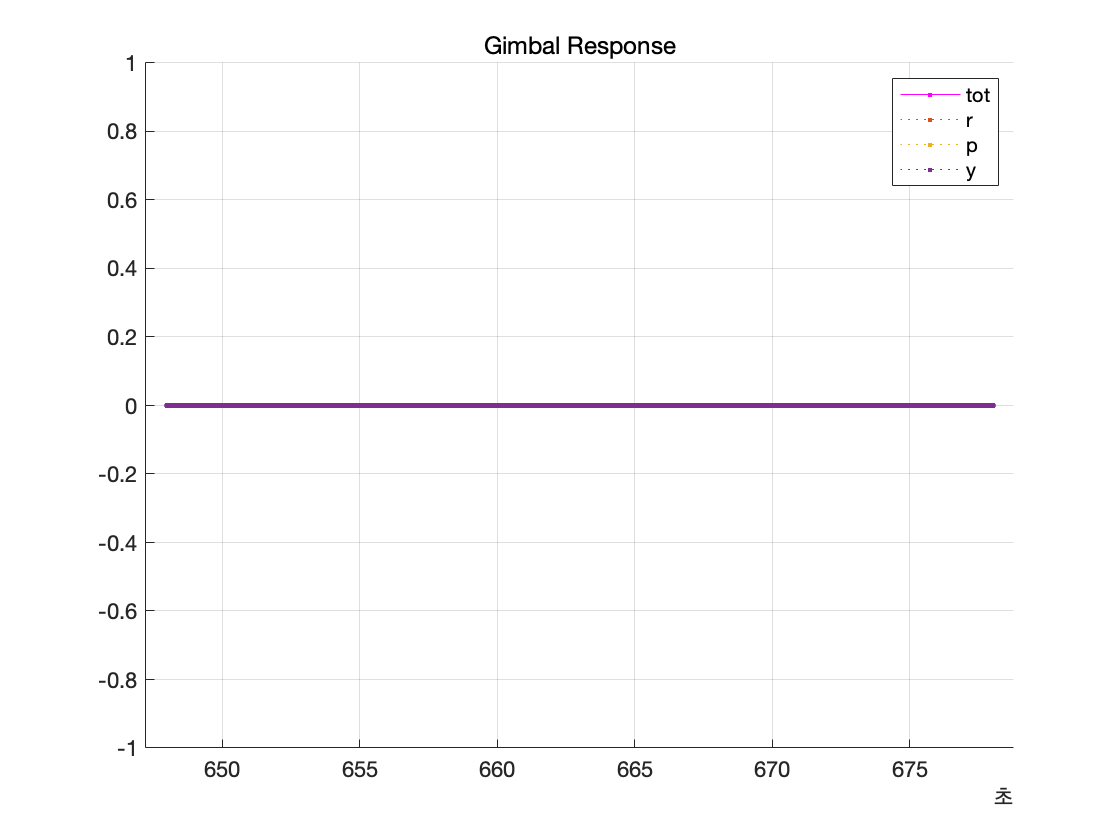

figure(13)
clf
hold on
grid on
title('Gimbal Response')
plot(time,gimbaldev(range),'m.-')
plot(time,data.gimbalRpy_deg_0(range),'.:')
plot(time,data.gimbalRpy_deg_1(range),'.:')
plot(time,data.gimbalRpy_deg_2(range),'.:')
legend('tot','r','p','y')

end

## Fcn definition - for transfer function estimation

This part shows the function that estimates the transfer function based on the data acquired from flight test. This part requires 'system ID toolbox'.

function [Num, Den, delay] = estimate_tf(n,mix,responseSet,cmdSet,testStartFlag,testFinishFlag)
global nN  nD
m = n;
if n>9
    m = n-9;
end
if mix>9
    mix = mix-9;
end
Cmd = cmdSet(testStartFlag(n):testFinishFlag(n)-1,m);
Response = responseSet(testStartFlag(n):testFinishFlag(n)-1,m);
if mix ~= m
    Response = responseSet(testStartFlag(n):testFinishFlag(n)-1,mix);
end
Cmd = detrend(Cmd,0);
Response = detrend(Response,0);

timeseriesSet = iddata(Response,Cmd,0.02);
sys = tfest(timeseriesSet,nD,nN,nan);
Num = sys.Numerator;
Den = sys.Denominator;
delay = sys.IODelay;
end
